Linnea

data = load("Linnea3.mat")

data = struct with fields:
    Acceleration: [1445×3 timetable]


kod

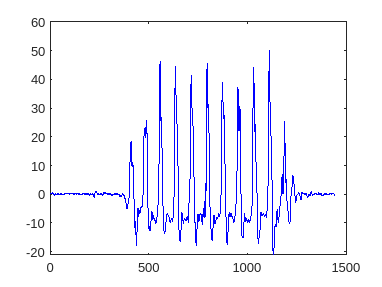


az = data.Acceleration.(3);
time = linspace(0, length(az)/100, length(az));
m = 55;
g = 9.8;

f = m * az;

v = cumtrapz(time, az - 10.2);

pos = cumtrapz(time, v);

plot(az-mean(az), 'b-');

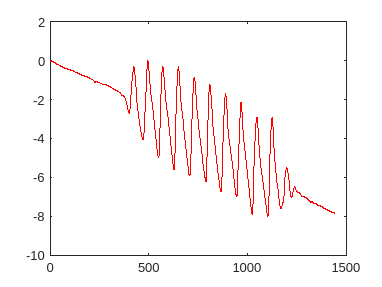

% hold on;

plot(v, 'r-');

% hold on;

plot(pos, 'g-');
legend('Acceleration', 'Velocity', 'Position in z-axis')

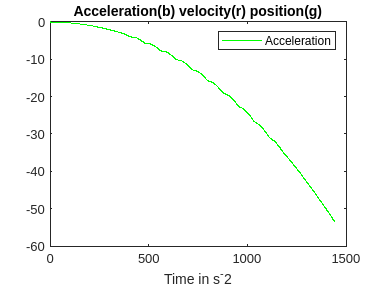

xlabel('Time in s^-2')
ylabel('')
title('Acceleration(b) velocity(r) position(g)')